% [10**7,10**7,2*10**7,2*10**7,9*10**5,9*10**5,8*10**5,8*10**5]
k = [10^7, 10^7, 2*10^7, 2*10^7, 9*10^5, 9*10^5, 8*10^5, 8*10^5];

% [0,0,0,0,8*10**3,8*10**3,8*10**3,8*10**3]
c = [0, 0, 0, 0, 8*10^3, 8*10^3, 8*10^3, 8*10^3];

% masses
m1 = 2300;
m2 = 300;
m3 = 380;
m4 = 250;
m5 = 400;

% h
h1 = 2.2;
h2 = 0.8;
h3 = 1.1;
h4 = 2.3;

% l
l1 = 2.4;
l2 = 2.2;
l3 = 0.9; 
l4 = 1;

% Inertia
I1 = 15000;

% L
L = 2;
 
% A
A = 0.35;

% v
v = 30;

delta_t = 0.002;
gamma = 0.5;
betta = 0.25;

%==============================================================================%
%Создаем матрицу коэффициентов упругости
v = v*1000/3600;                % Из км/ч переводим в м/c
T = round((l1 + l2 + L)/v, 2);  % Округляем до второго знака время необходимое на преодоления кочек

T = 0:delta_t:(T+0.401);
round(T, 3);

N = length(T); % Находим кол-во элементов в массиве времени

t_matrix = [(l2-l2)/v,(l2-l4)/v, (l2+l3)/v,(l2+l1)/v];
t_matrix = round(t_matrix, 3);

% временная переменная для 
%temp_var = ;

n_itit = round((L/v)/delta_t, 0);

r = linspace(0, 5, n_itit); %
sinus = zeros(1, length(r));
for i = 1:1:length(r)
    sinus(i) = sinys(r(i), A, L);
end

K_diag = diag(k);
D = [-1,h1,1,0,0,0;
     -1,h2,0,1,0,0;
     -1,h3,0,0,1,0;
     -1,h4,0,0,0,1;
     1,-l1,0,0,0,0;
     1,-l3,0,0,0,0;
     1,l4,0,0,0,0;
     1,l2,0,0,0,0];
K = D' * K_diag * D;

C_diag = diag(c);
C = [0,0,0,0,0,0;
     0,0,0,0,0,0;
     0,0,0,0,0,0;
     0,0,0,0,0,0;
     1,-l1,0,0,0,0;
     1,-l3,0,1,0,0;
     1,l4,0,0,1,0;
     1,l2,0,0,0,0];
C = C' * C_diag * C;


M = [m1, 0, 0, 0, 0, 0;
     0, I1, 0, 0, 0, 0;
     0, 0, m2, 0, 0, 0;
     0, 0, 0, m3, 0, 0;
     0, 0, 0, 0, m4, 0;
     0, 0, 0, 0, 0, m5];

%M = diag(temp_var);

n = size(D, 1) - length(t_matrix) + 1;
y_voz = zeros(n, N);
y_voz(1,:) = T;

% вместо where
index_t = t_matrix * 1000 / 2;
 

for i = index_t + 1%
    % С дебильной нумерацией массивов с "1" а не с "0" приходится мириться
    temp_sin_m = sinus;
    if (i > 0)
        temp_zeros_m = zeros(1, i - 1);
        temp_sin_m = cat(2, temp_zeros_m, sinus);
    end

    temp_zeros_m = zeros(1, N - n_itit - i + 1);
    fin_m = cat(2, temp_sin_m, temp_zeros_m);
    y_voz = cat(1, y_voz, fin_m);
    n = n + 1;
end
    
y_impact = y_voz;
y_impact(1, :) = [];

% Создаем обратную матрицу
temp_var = M+delta_t*gamma*C+delta_t^2*betta*K;

M_reverse = inv(temp_var);
K_diag_transpose = D' * K_diag;

X = zeros(size(K_diag_transpose, 1), 1);
X_t = zeros(size(K_diag_transpose, 1), 1);
X_tt = zeros(size(K_diag_transpose, 1), 1);


for i = 1:1:N
    % Формируем матрицы методом Ньюмарка
    % Ускорений
    F = K_diag_transpose*y_impact(:,i) - ...
        C*(X_t(:,size(X_t,2)) + delta_t*(1-gamma)*X_tt(:,size(X_tt,2))) - ...
        K*(X(:,size(X,2)) + delta_t*X_t(:,size(X_t,2)) + 1/2*delta_t^2*(1-2*betta)*X_tt(:,size(X_tt,2)));
    X_tt = cat(2, X_tt, (M_reverse*F));
    % Скоростей
    X_tn = X_t(:,i)+delta_t*(gamma*X_tt(:,size(X_tt,2))+(1-gamma)*X_tt(:,i));
    X_t = cat(2, X_t, X_tn);
    % Перемещений
    X_n = X(:,i)+delta_t*X_t(:,i)+0.5*(delta_t^2)*(2*betta*X_tt(:,size(X_tt,2)) + (1-2*betta)*X_tt(:,i));
    X = cat(2, X, X_n);
end

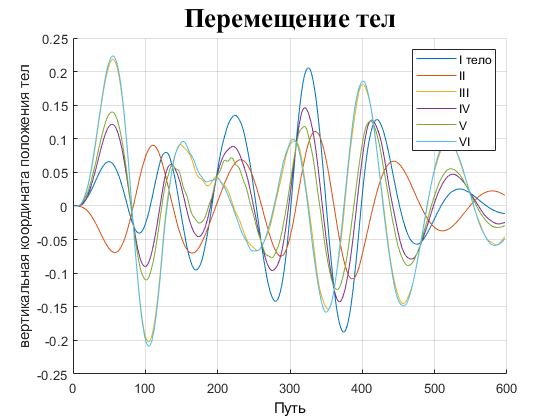

% Графики
figure;
hold on;
for i = 1:1:size(X,1)
    plot(X(i,:));
end

title('Перемещение тел', fontsize=20, fontname='Times New Roman')
xlabel('Путь', color='black')
ylabel('вертикальная координата положения тел')
grid on
legend('I тело','II','III','IV','V','VI')

hold off;

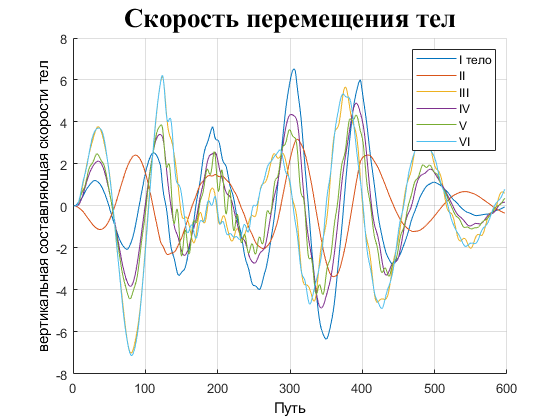


figure;
hold on;
for i = 1:1:size(X_t,1)
    plot(X_t(i,:));
end

title('Скорость перемещения тел', fontsize=20, fontname='Times New Roman')
xlabel('Путь', color='black')
ylabel('вертикальная составляющая скорости тел',color='black')
grid on;
legend('I тело','II','III','IV','V','VI')

hold off;

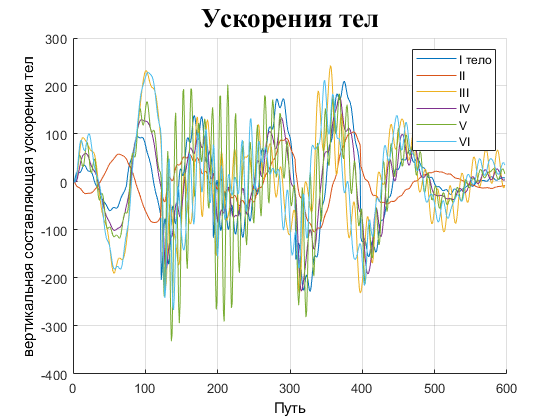


figure;
hold on;
for i = 1:1:size(X_tt,1)
    plot(X_tt(i,:));
end

title('Ускорения тел', fontsize=20, fontname='Times New Roman')
xlabel('Путь', color='black')
ylabel('вертикальная составляющая ускорения тел',color='black')
grid on
legend('I тело','II','III','IV','V','VI')

hold off;

function [r_num] = rounded(num)
    r_num = round(num, 3);
    if(mod((r_num * 1000), 2) ~= 0)
        r_num = r_num + 0.001;
    end
end

% sinus(i) = sinys(r(i), A, L);

function [sin_val] = sinys(t, amplisuda, L)% 
    local_var = pi * t/L;
    sin_val = amplisuda * sin(local_var);
end 